# Demo of CSS

The following is a demo the CSS. The first section generates a sample smoothed image, the second section calls the CSS function, in the third section is the permutation test for the cluster-level significance, and the last section displays the selected significant clusters. In the meantime, we obtain the cluster-size thresholding results as reference.

### Section 1

In the example, we generate a $100\times 100$ 2D image. The truth consists of two clusters, generated by adding a group difference (effect size=0.2) to the null image and smoothed with Gaussian kernel at FWHM=8mm. According to this setting, the smoothness parameter to estimate the dependence structure is 4 (in the CSS_2D(..., smt, ...). Each arm has 30 subjects and the primary threshold is 0.001.

%%%-----making sample image-----%%%
%create a mask for dim detection
mask=zeros(100,100);

%smoothness parameters
newsigma=8/(2*sqrt(8*log(2)));

%effect size (group difference)
es=0.2;

%generate images
data=zeros(100,100);
data(37:46,37:46)=1; 
data(56:60,40:41)=1;

%# subjects per arm
arm=30;
%primary threshold
p_val=0.001;
%smoothness parameter
smt=4;
data1d=data(:);

%optional output for smoothed image underlying truth and indices
%truth=data1d;
%truthidx=find(data1d>0);
%figure;imagesc(data);colormap jet;colorbar;
%orgidx=truthidx;

image_data=randn(10000,arm*2);
image_data_blur=zeros(size(image_data));
for k=1:arm*2
    image_data2d_sub=reshape(image_data(:,k),size(data));
    image_data2d_sub_blur = imgaussfilt(image_data2d_sub, newsigma);
    image_data_blur(:,k)= reshape(image_data2d_sub_blur,numel(image_data2d_sub_blur ),1) ;
end
image_data_blur(data1d>0,1:arm)=image_data_blur(data1d>0,1:arm)+es;

### **Section 2**

In this section, we first calculate the T-map and p-values for each voxel. We display the T-map as additional information. The function CSS_2D is applied to calculate the CSS for 2D images. Note that the CSS for 3D images is also available in the repository. The corresponding function is CSS_3D.

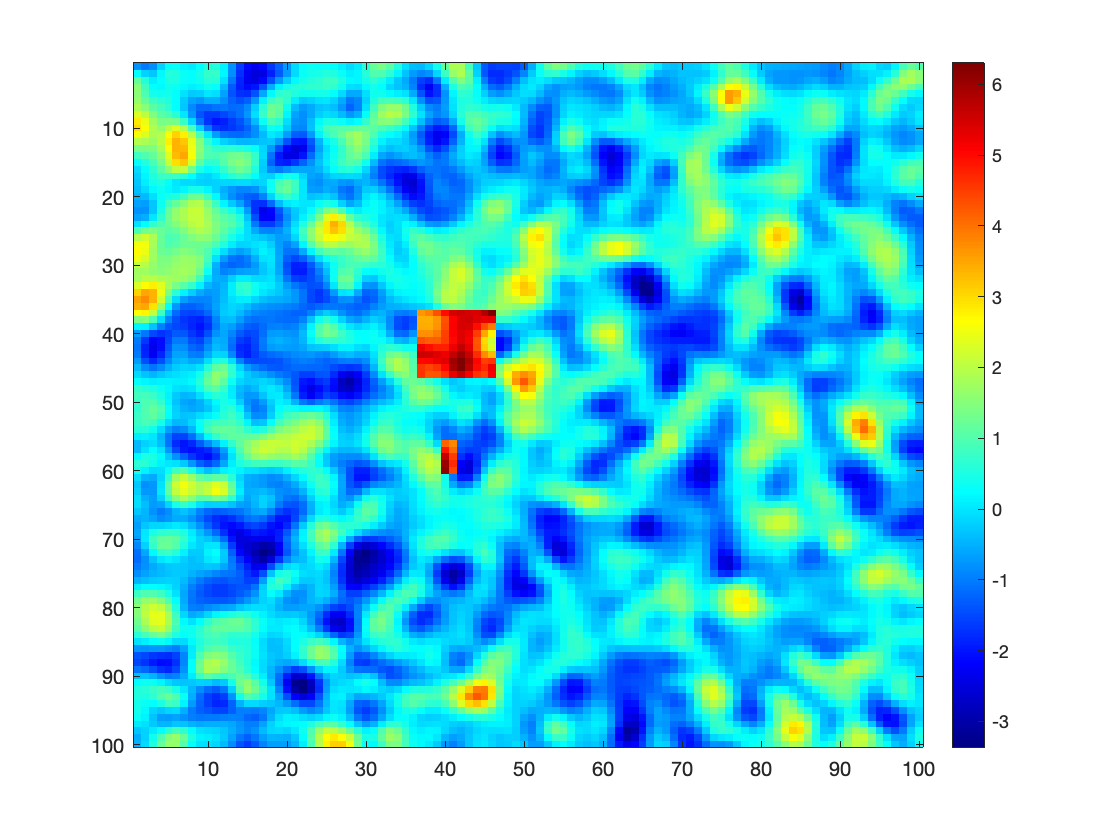

T=zeros(size(data1d));
P=zeros(size(data1d));
for j=1: (size(image_data_blur,1))
    x=image_data_blur(j,1:arm);
    y=image_data_blur(j,(arm+1):arm*2);
    T(j)=(mean(x)-mean(y))/sqrt(var(x)/arm+var(y)/arm);
    P(j)=2*(1-tcdf(abs(T(j)),2*arm-2));
end
figure;imagesc(reshape(T,100,100));colormap jet;colorbar;

[P_chern,P_com,C_sig,phi,f,var_c,cluster_size]=CSS_2D(P,image_data_blur,mask,smt,p_val);

### **Section 3**

The permutation test is conducted in this section. We permute the label 100 times for the sake of time, but it is recommended to set this number to at minimum 500. 

%Permutation test
M=100; 
P_min=zeros(M,1);
parfor m=1:M
    group_perm1= randsample(arm*2,arm);
    group_perm0=setdiff(1:arm*2,group_perm1);
    order=[group_perm1' group_perm0];
    P1=zeros(size(data1d));
    T1=zeros(size(data1d));
    for j=1: (size(image_data_blur,1))
        x=image_data_blur(j,group_perm1);
        y=image_data_blur(j,group_perm0);
        T1=(mean(x)-mean(y))/sqrt(var(x)/arm+var(y)/arm);
        P1(j)=2*(1-tcdf(abs(T1),2*arm-2));
    end
    
    [P_chern1,~,~,~,~,~,cluster_size1]=CSS_2D(P1,image_data_blur(:,order),mask,smt,p_val);
    
    P_min(m)=min(P_chern1);
    T_max(m)=max(cluster_size1);
    
end

**Section 4**

The FWER is controlled at 5% for CSS and cluster-size thresholds. In the end, we draw the significant cluster(s) detected from CSS and cluster-size threshold on the null image. 

%output CSS threshold
P_min=sort(P_min);
p_chrf=P_min(.05*M+1)

p_chrf = 8.8881e-09


%output cluster-size threshold
T_max=sort(T_max);
perm_size=T_max(.95*M-1)

perm_size = 11

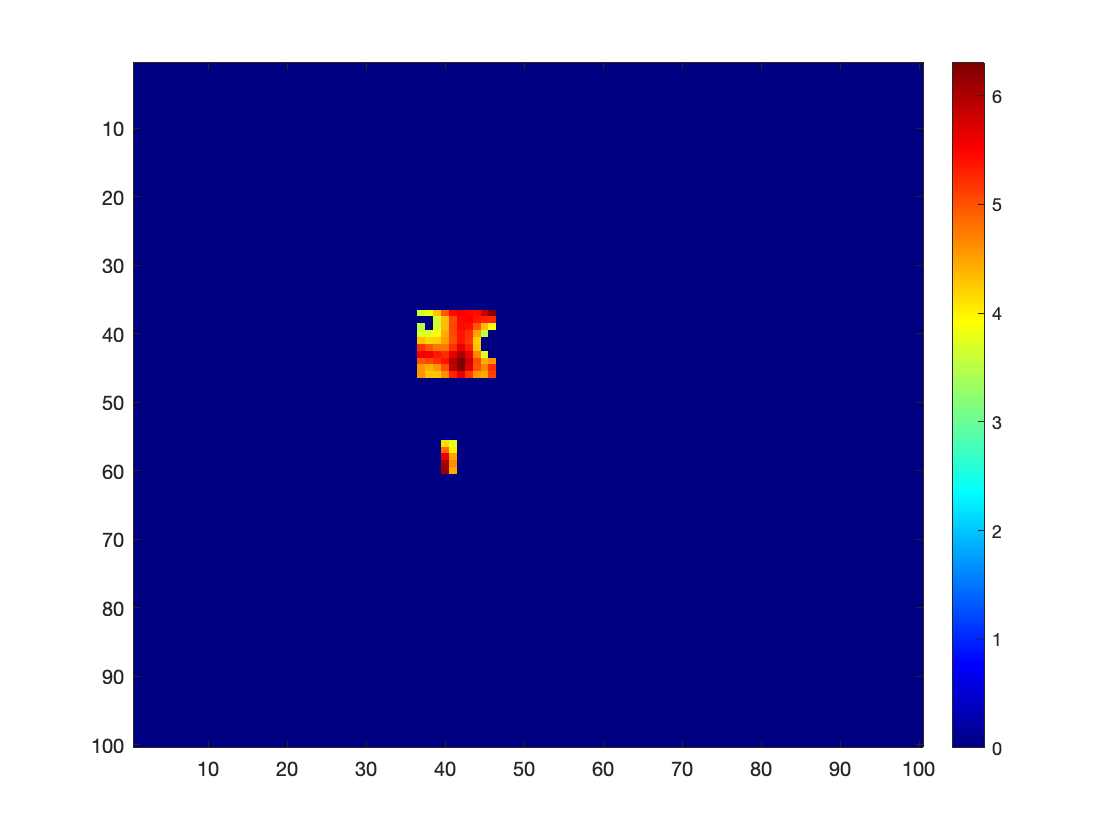


%output indices
idx_chrf=vertcat(C_sig{1,P_chern<=p_chrf});
idx_size=vertcat(C_sig{1,cluster_size>=perm_size});
output_img=zeros(size(mask));
out1d=output_img(:);
out2d=output_img(:);
out1d(idx_chrf)=T(idx_chrf);
out2d(idx_size)=T(idx_size);
final_chrfimg=reshape(out1d,size(mask));
final_sizeimg=reshape(out2d,size(mask));
figure;imagesc(final_chrfimg);colormap jet;colorbar;
hold on

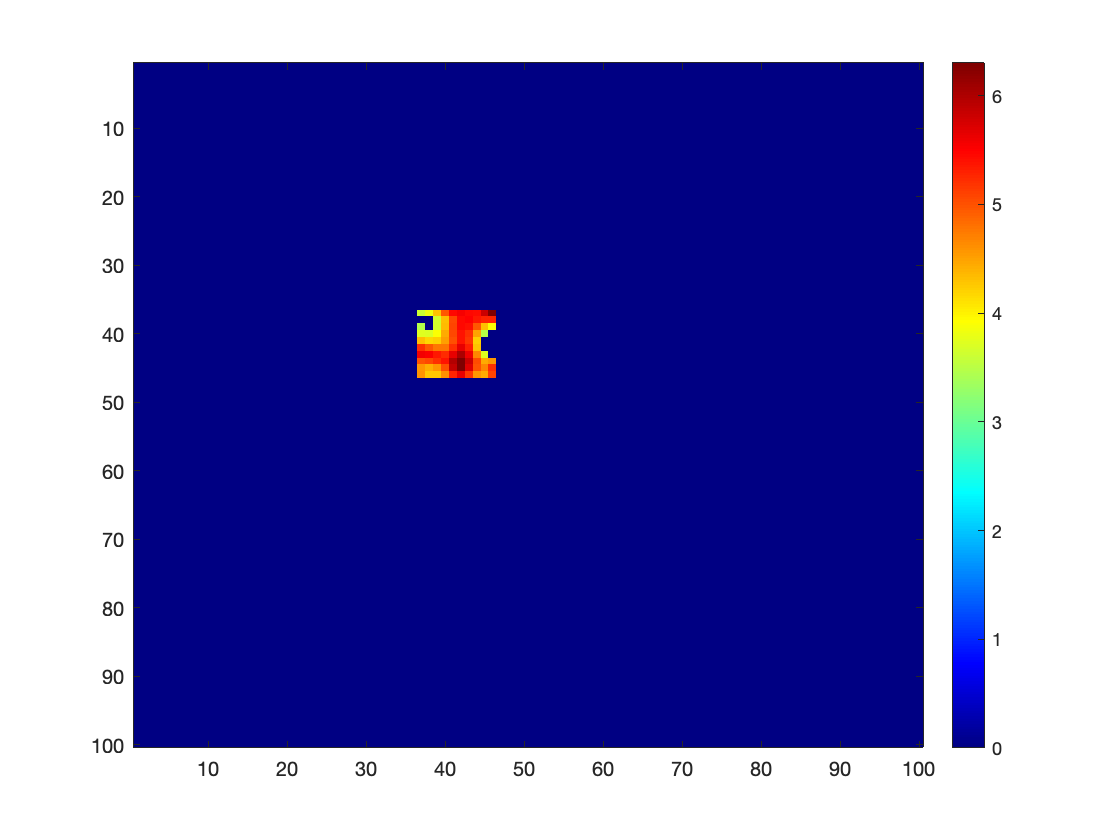

figure;imagesc(final_sizeimg);colormap jet;colorbar;
hold off